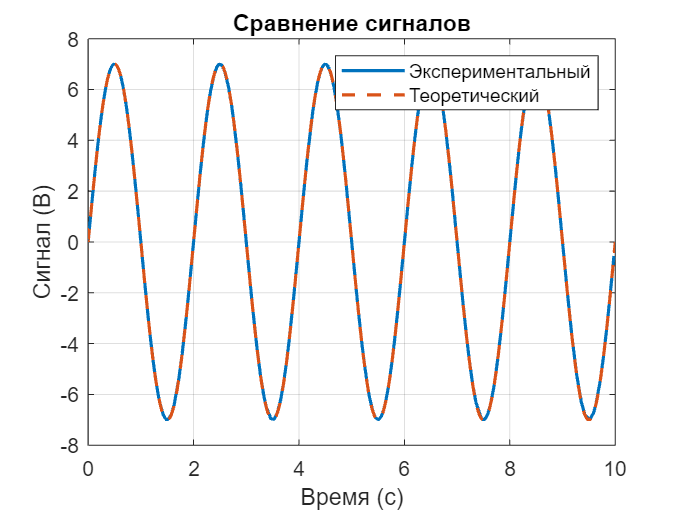

close all
clc
clear

k = 2.5127;
T = 0.1181;

% Параметры
A1 = 7; % Амплитуда сигнала (В)
w1 = 2 * pi * 0.5; % Частота (рад/с)
sim_time = 10; % Время симуляции (с)

% Параметры
filename = 'task5_1_20241009_133719.csv'; % Укажите имя файла

% Чтение экспериментальных данных из CSV-файла
data = readtable(filename);
time = data{:, 1};       % Время (с)
signal = data{:, 2};     % Сигнал (В)
theta = data{:, 3};      % Угол (градусы)
theta = theta - theta(1);
theta = theta * pi / 180;
omega = data{:, 4}; % Угловая скорость (град/с)
omega = omega * pi / 180;

% чтобы симулинк не ругался
A2 = 0;
w2 = 0;
A3 = 0;
w3 =0;

% Настройка модели Simulink
model_name = 'sim5'; % Имя модели Simulink
sw = 1;
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StopTime', num2str(sim_time));  % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

time_sim = sim_out.theta.Time;
theta_sim = sim_out.theta.Data;
omega_sim = sim_out.omega.Data;
input_signal_sim = sim_out.input_signal.Data;

% График сигнала
figure;
plot(time, signal, 'LineWidth', 1.5);
hold on;
plot(time_sim, input_signal_sim, '--', 'LineWidth', 1.5);
grid on;
title('Сравнение сигналов');
xlabel('Время (с)');
ylabel('Сигнал (В)');
legend('Экспериментальный', 'Теоретический');

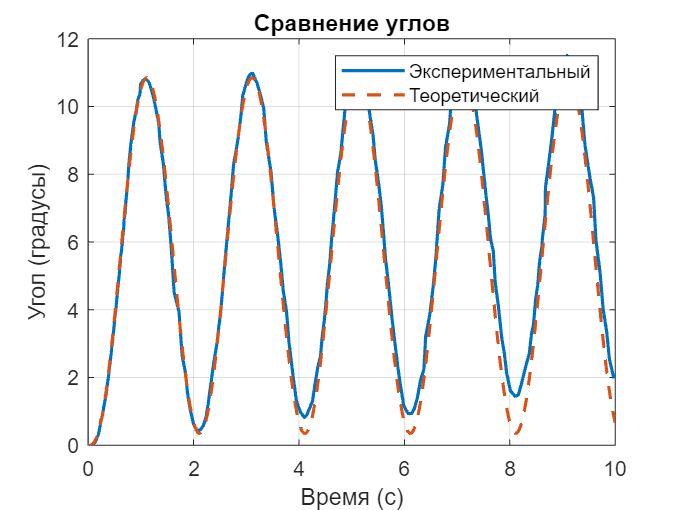


% График угла
figure;
plot(time, theta, 'LineWidth', 1.5);
hold on;
plot(time_sim, theta_sim, '--', 'LineWidth', 1.5);
grid on;
title('Сравнение углов');
xlabel('Время (с)');
ylabel('Угол (градусы)');
legend('Экспериментальный', 'Теоретический');

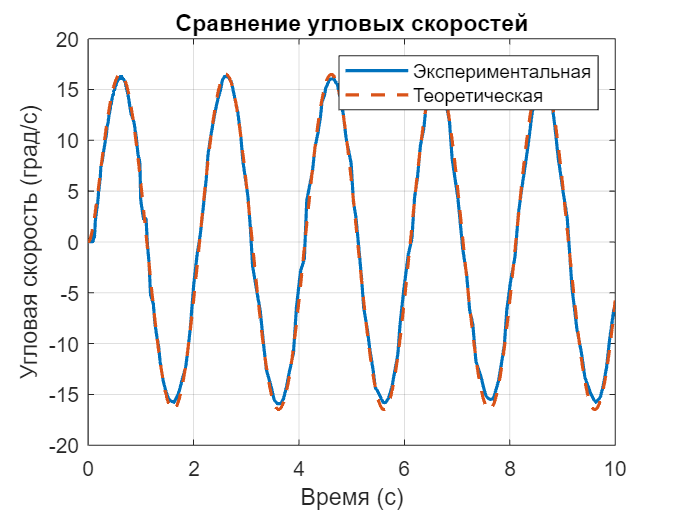


% График угловой скорости
figure;
plot(time, omega, 'LineWidth', 1.5);
hold on;
plot(time_sim, omega_sim, '--', 'LineWidth', 1.5);
grid on;
title('Сравнение угловых скоростей');
xlabel('Время (с)');
ylabel('Угловая скорость (град/с)');
legend('Экспериментальная', 'Теоретическая');

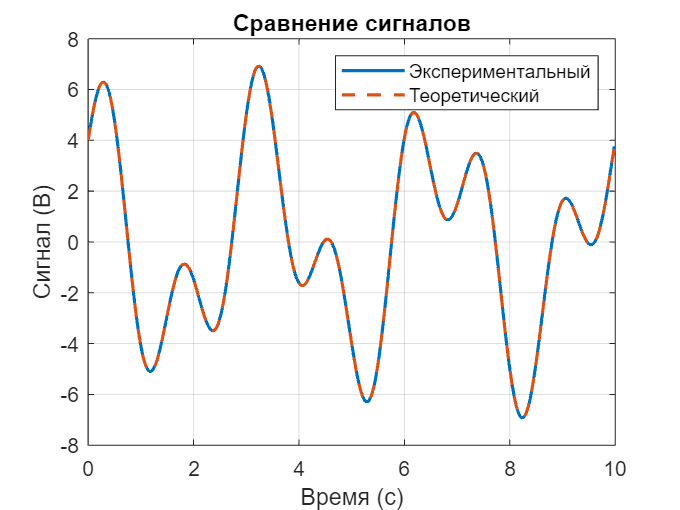

close all
clc
clear

k = 2.5127;
T = 0.1181;

% Параметры
A2 = 4.0;
w2 = 2 * pi * 0.3;
A3 = 3.0;
w3 = 2 * pi * 0.7;
sim_time = 10; % Время симуляции (с)

% Параметры
filename = 'task5_2_20241009_133814.csv'; % Укажите имя файла

% Чтение экспериментальных данных из CSV-файла
data = readtable(filename);
time = data{:, 1};       % Время (с)
signal = data{:, 2};     % Сигнал (В)
theta = data{:, 3};      % Угол (градусы)
theta = theta - theta(1);
theta = theta * pi / 180;
omega = data{:, 4}; % Угловая скорость (град/с)
omega = omega * pi / 180;

% чтобы симулинк не ругался
A1 = 0;
w1 = 0;

% Настройка модели Simulink
model_name = 'sim5'; % Имя модели Simulink
sw = 2;
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StopTime', num2str(sim_time));  % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

time_sim = sim_out.theta.Time;
theta_sim = sim_out.theta.Data;
omega_sim = sim_out.omega.Data;
input_signal_sim = sim_out.input_signal.Data;

% График сигнала
figure;
plot(time, signal, 'LineWidth', 1.5);
hold on;
plot(time_sim, input_signal_sim, '--', 'LineWidth', 1.5);
grid on;
title('Сравнение сигналов');
xlabel('Время (с)');
ylabel('Сигнал (В)');
legend('Экспериментальный', 'Теоретический');

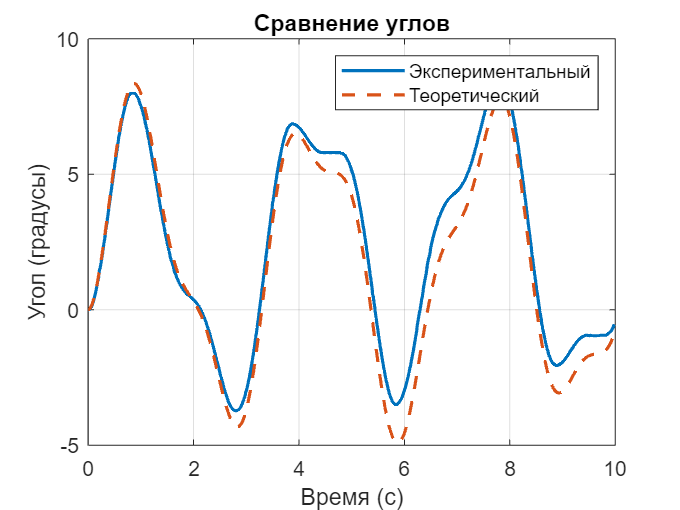


% График угла
figure;
plot(time, theta, 'LineWidth', 1.5);
hold on;
plot(time_sim, theta_sim, '--', 'LineWidth', 1.5);
grid on;
title('Сравнение углов');
xlabel('Время (с)');
ylabel('Угол (градусы)');
legend('Экспериментальный', 'Теоретический');

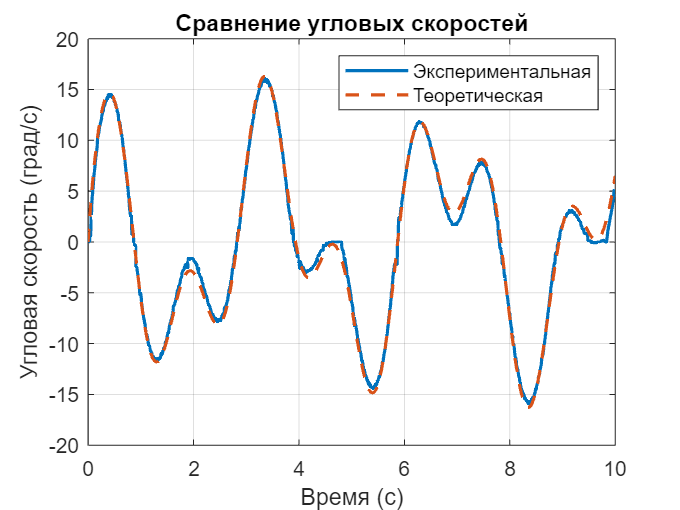


% График угловой скорости
figure;
plot(time, omega, 'LineWidth', 1.5);
hold on;
plot(time_sim, omega_sim, '--', 'LineWidth', 1.5);
grid on;
title('Сравнение угловых скоростей');
xlabel('Время (с)');
ylabel('Угловая скорость (град/с)');
legend('Экспериментальная', 'Теоретическая');